% Load the detector
load("frcnn_rNet18_Detector_aug4signs_10e.mat");


% Prompt the user to select an image file
[fileName, filePath] = uigetfile({'*.jpg;*.png;*.jpeg;*.bmp', 'Image Files (*.jpg, *.png, *.jpeg, *.bmp)'}, 'Select an Image File');
if fileName == 0
    % User canceled the file selection
    disp('No image selected. Exiting.');
    return;
end

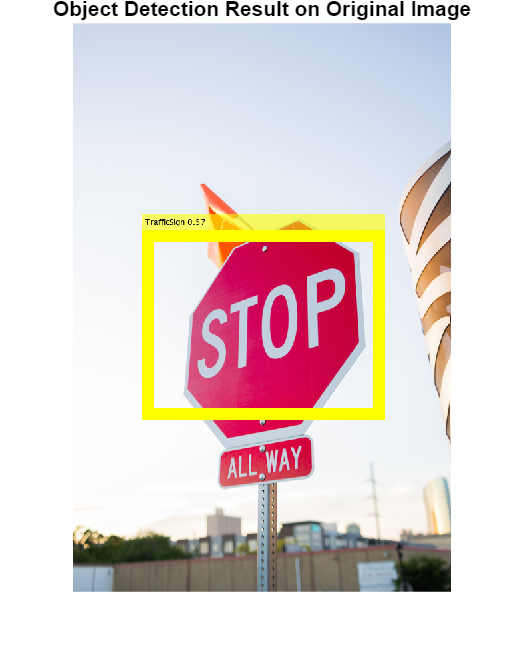


% Construct the full path to the selected image
selectedImagePath = fullfile(filePath, fileName);
inputSize = [224 224 3];

% Read the selected image
originalImage = imread(selectedImagePath);

% Resize the image to match the input size expected by the detector
I = imresize(originalImage, inputSize(1:2));

% Detect objects in the resized image
[bbox, score, label] = detect(detector, I);

% Check if no objects were detected
if isempty(score)
    disp('No objects detected.');
else
    % Annotate the original image with adjusted bounding boxes
    scaleX = size(originalImage, 2) / inputSize(2);
    scaleY = size(originalImage, 1) / inputSize(1);
    for i = 1:length(score)
        scoreStr = sprintf('%.2f', score(i));
        labelStr = [char(label(i)), ' ', scoreStr];
        
        % Adjust bounding box coordinates to match the original image size
        adjustedBbox = [bbox(i, 1) * scaleX, bbox(i, 2) * scaleY, bbox(i, 3) * scaleX, bbox(i, 4) * scaleY];
        
        originalImage = insertObjectAnnotation(originalImage, 'rectangle', adjustedBbox, labelStr, 'LineWidth', 18, 'FontSize', 12);
    end

    % Display the original image with the detection results
    figure
    imshow(originalImage);
    title('Object Detection Result on Original Image');
end